# Ejemplo de uso: wsa_dft

Se muestran ejemplos del uso de la función wsa_dft.

#### Ruta a funciones

addpath('..\');

#### Transformada discreta de Fourier de una señal sinusoidal pura

Se calcula la transformada discreta de Fourier (DFT) a una señal coseno con frecuencia angular de $\frac{1}{2}$ rad/s:


$$x[n] = \frac{1}{2}cos\left(\frac{1}{2} n\right)$$


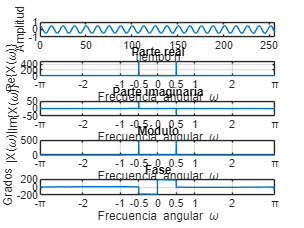

n = 0:1:2047;
x_n = 0.5*cos((1/2)*n);
[X, W] = wsa_dft(x_n, 2048);

figure;
subplot(5, 1, 1)
plot(n, x_n)
xlabel("tiempo n")
ylabel("Amplitud")
xlim([0, 256])
ylim([-1, 1])

subplot(5, 1, 2); plot(W, real(X)); grid; title('Parte real');
xlim([-pi, pi])
xticks([-pi, -2, -1, -0.5, 0, 0.5, 1, 2, pi])
xticklabels({"-π", -2, -1, -0.5, 0, 0.5, 1, 2, "π"})
xlabel("Frecuencia angular \omega")
ylabel('Re\{X(\omega)\}')
subplot(5, 1, 3); plot(W, imag(X)); grid; title('Parte imaginaria');
xlim([-pi, pi])
xticks([-pi, -2, -1, -0.5, 0, 0.5, 1, 2, pi])
xticklabels({"-π", -2, -1, -0.5, 0, 0.5, 1, 2, "π"})
xlabel("Frecuencia angular \omega")
ylabel('Im\{X(\omega)\}')
subplot(5, 1, 4); plot(W, abs(X)); grid; title('Módulo');
xlim([-pi, pi])
xticks([-pi, -2, -1, -0.5, 0, 0.5, 1, 2, pi])
xticklabels({"-π", -2, -1, -0.5, 0, 0.5, 1, 2, "π"})
xlabel("Frecuencia angular \omega")
ylabel('|X(\omega)|')
subplot(5, 1, 5); plot(W, 180/pi*angle(X));grid; title('Fase');
xlim([-pi, pi])
xticks([-pi, -2, -1, -0.5, 0, 0.5, 1, 2, pi])
xticklabels({"-π", -2, -1, -0.5, 0, 0.5, 1, 2, "π"})
xlabel("Frecuencia angular \omega")
ylabel('Grados');